# **Estimating homography**

In this example we will estimate homographies from a set of checkboard images. Estimating homographies is the first step of the Zhang's calibration method.

## Load and display images

Let the images be located in a subfolder of the current folder called `images`.

% Load an image containing the checkerboard pattern
imageFileName = fullfile('images','image1.tif'); 
I = imread(imageFileName);

Let's check the size and type of the data (called "class" in Matlab)

size(I)
class(I)

Visualize the image

figure
imshow(I)

Images may be inspected using `impixelinfo`:

impixelinfo

## Detect checkerboard points

To estimate homographies, we need *a set of correspondences (at least four) between 3D points lying on the checkerboard patten and 2D points in the image*. The size of the squares of the pattern is 30mm. A function is available in the Computer Vision Toolbox, for detecting the checkerboard points:

[imagePoints, boardSize] = detectCheckerboardPoints(I)

## Visualizing the detected points

Let's visualize the detected points by superimposing text and markers to the image.

figure
imshow(I)
hold on %to allow multiple superimposed drawings of the same figure
for ii=1:size(imagePoints,1)
    plot(imagePoints(ii,1),imagePoints(ii,2),'or') %o for circle and r for red
    hndtxt=text(imagePoints(ii,1),...
        imagePoints(ii,2),...
        num2str(ii));
    set(hndtxt,'fontsize',8,'color','green');
end

The X direction is the long side and the Y is the short side.

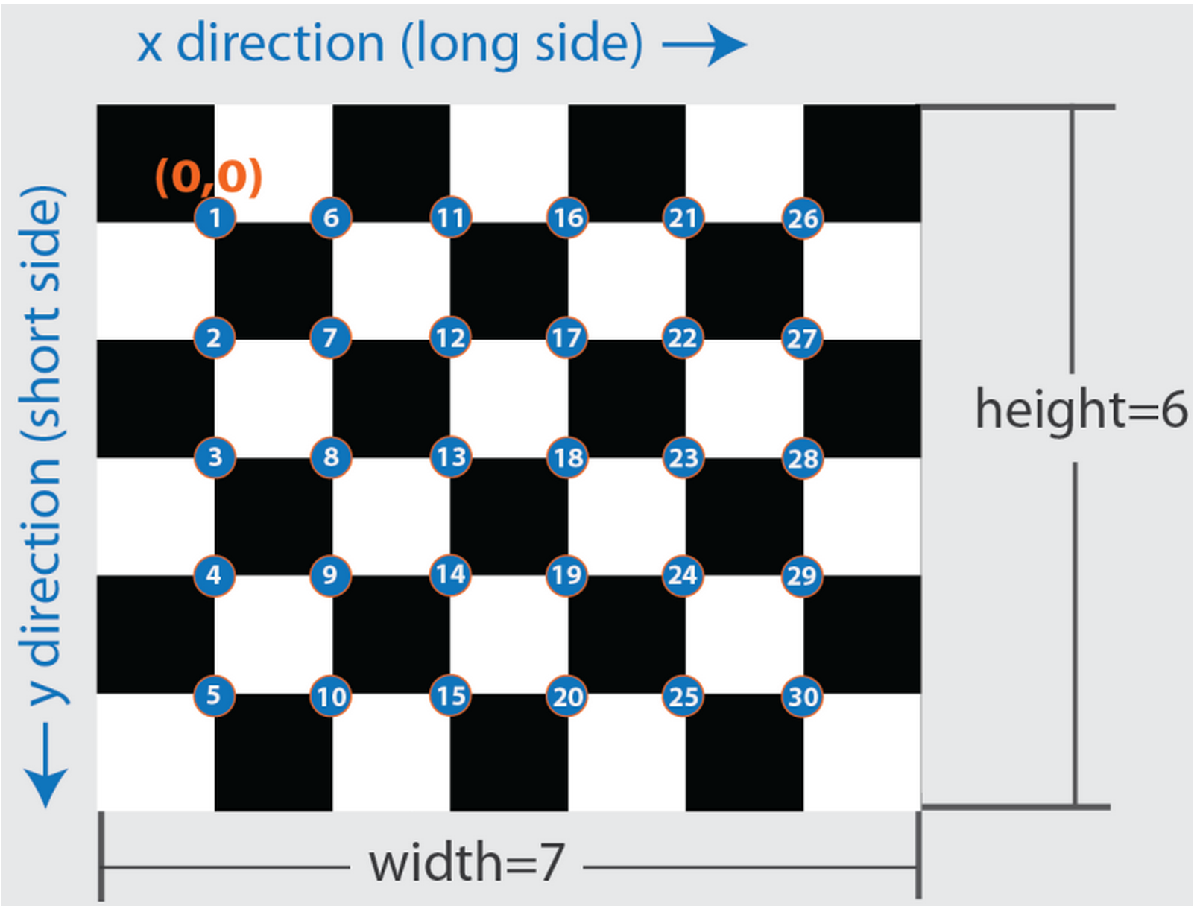

## Processing many images

We now load four images, detect the interest points and store the images `I` and the points `XYpixel` in the structure array `imageData`.

 
 
  clear imageData
  iimage=[1 4 7 10];
  
  for ii=1:length(iimage)
      imageFileName = fullfile('images',['image' num2str(iimage(ii)) '.tif']);
      
      imageData(ii).I = imread(imageFileName);
   
      imageData(ii).XYpixel = detectCheckerboardPoints(imageData(ii).I); %#ok
      

      hnd=figure; %when creating a figure, a handle is returned, that can be used for accessing properties
      imshow(imageData(ii).I)
      hold on
      
      for jj=1:size(imageData(ii).XYpixel,1)
            x=imageData(ii).XYpixel(jj,1);
            y=imageData(ii).XYpixel(jj,2);
            plot(x,y,'or')
            
            hndtxt=text(x,y,num2str(jj));
            set(hndtxt,'fontsize',8,'color','green');
      end
      % pause (1)
      % close (hnd) 
  end  
 

## Establishing correspondences

Now, given that the square size is 30mm and that the detected points are ordered, we can establish correspondences.

squaresize=30; % [mm]
  
    for ii=1:length(iimage)
      figure
      imshow(imageData(ii).I)
      
      XYpixel=imageData(ii).XYpixel;
      clear Xmm Ymm
      for jj=1:length(XYpixel)
          [row,col]=ind2sub([12,13],jj); %linear index to row,col 
          
          Xmm=(col-1)*squaresize;
          Ymm=(row-1)*squaresize;
          
          imageData(ii).XYmm(jj,:)=[Xmm Ymm];
         
          hndtxt=text(XYpixel(jj,1),...
              XYpixel(jj,2),...
              num2str([Xmm Ymm]));
          set(hndtxt,'fontsize',8,'color','cyan');
            
      end
     
    end

## Estimating homographies

Now, the field `XYmm` contains the coordinates in millimeters along the checkerboard and the field `XYpixel` the coordinates of the corresponding pixel in the image. Thus, the correspondences have been established.

Remember that to estimate the homography we need to estimate the 3x3 matrix $H$in the following:


$$w \left[
\begin{array}{c}
u \\ 
v \\ 
1
\end{array} 
\right]=P
\left[
\begin{array}{c}
x \\ 
y \\ 
0 \\
1
\end{array} 
\right]=
\left[
p_1 \; p_2 \; p_3 \; p_4
\right]
\left[
\begin{array}{c}
x \\ 
y \\ 
0 \\
1
\end{array} 
\right]=
\underbrace{\left[
p_1 \; p_2 \;  p_4
\right]}_{\doteq H}
\underbrace{\left[
\begin{array}{c}
x \\ 
y \\ 
1
\end{array} 
\right]}_{\doteq m}$$


where $u,v$ are the pixel coordinates and $x,y$ the mm coordinates. 

By partitioning $H$row-wise as


$$H=\left[
\begin{array}{c}
h_1^\top \\ 
h_2^\top \\ 
h_3^\top
\end{array} 
\right]$$


we obtain two homogeneous equations for each correspondence:

$\left[
\begin{array}{ccc}
m^\top & 0^\top & -um^\top \\ 
0^\top & m^\top & -vm^\top 
\end{array} 
\right]
\left[
\begin{array}{c}
h_1 \\ 
h_2 \\ 
h_3
\end{array} 
\right]=0$.

We need to stack the equations and get a homogeneous linear system of equations such as:


$$Ax=0$$


that we can solve in the least squares sense under the constraint that

$x \neq 0$.

The solution is the right singular value of $A=U\Sigma V^\top$ associated with the smallest singular value, i.e. the rightmost column of $V$.

  
  
  
    for ii=1:length(iimage)
      XYpixel=imageData(ii).XYpixel;
      XYmm=imageData(ii).XYmm;
      A=[];
      b=[];
      for jj=1:length(XYpixel)
           
          Xpixel=XYpixel(jj,1);
          Ypixel=XYpixel(jj,2);
          Xmm=XYmm(jj,1);
          Ymm=XYmm(jj,2);
         
          
          m=[Xmm; Ymm; 1];
          O=[0;0;0];
          A=[A; m' O' -Xpixel*m';O' m' -Ypixel*m']; %#ok
          b=[b;0;0]; %#ok
                
      end
      [U,S,V]=svd(A);
      h=V(:,end); % the right  singular vector associated to the smallest singular value
      
      imageData(ii).H=reshape(h,[3 3])'; %reshape acts column-wise so we neet to transpose
 
    end
  
  

## Superimposing a circle to the checkerboard

Now to check the reprojection, we superimpose a circe lying in the checkerboard plane to the images. 

  % reprojection: superimpose a circle to each image
  % take an image
  for ii=1:length(iimage)
      figure
      imshow(imageData(ii).I)
      hold on

      vtheta=0:0.01:2*pi;
      centerX=150;
      centerY=150;
      radius=100;
      vX=centerX+radius*cos(vtheta);
      vY=centerY+radius*sin(vtheta);
     
      homogeneous = [vX; vY; ones(1,length(vtheta))];
      proj_hom=imageData(ii).H*homogeneous;
      
      proj=[ proj_hom(1,:)./proj_hom(3,:);...
          proj_hom(2,:)./proj_hom(3,:)];

      plot(proj(1,:),proj(2,:),'gs');
     
  end

## Homework

1) calibrate using Zhang procedure (find the intrinsic parameters $K$ and, for each image, the pair of $R,t$ (extrinsic) 

2) superimpose a cilinder (or a solid of your choice) to each image